page55

clc; clf; clearvars;
syms x t s u(x,t) U(x,s) u0 Y(x)
Dt = diff(u,t);
D2x = diff(u,x,2);
eqn = laplace(Dt== D2x,t,s);
cond0 = u(0,t) == 0;
cond1 =u(1,t) == u0;
eqn = subs(eqn, {laplace(u,t,s),u(x,0),laplace(D2x,t,s)},{U(x,s),0,subs(D2x,{u,t},{U,s})})

$$eqn(x) = s\,U\left(x,s\right)=\frac{\partial^{2}}{\partial x^{2}}U\left(x,s\right)$$

cond0_s = laplace(cond0,t,s);
cond1_s = laplace(cond1,t,s);
cond0_s = subs(cond0_s,laplace(u(0,t),t,s),U(0,s))

$$cond0\_s = U\left(0,s\right)=0$$

cond1_s = subs(cond1_s,laplace(u(1,t),t,s),U(1,s))

$$cond1\_s = U\left(1,s\right)=\frac{u_{0}}{s}$$

eqn_n = subs(eqn,U,Y)

$$eqn\_n(x) = s\,Y\left(x\right)=\frac{\partial^{2}}{\partial x^{2}}Y\left(x\right)$$

cond0_s = subs(cond0_s,U,Y)

$$cond0\_s = Y\left(0\right)=0$$

cond1_s = subs(cond1_s,U,Y)

$$cond1\_s = Y\left(1\right)=\frac{u_{0}}{s}$$

sol = dsolve(eqn_n,[cond0_s cond1_s])

$$sol = \frac{u_{0}\,{\mathrm{e}}^{-\sqrt{s}\,x}\,{\mathrm{e}}^{\sqrt{s}}\,\left({\mathrm{e}}^{2\,\sqrt{s}\,x}-1\right)}{s\,\left({\mathrm{e}}^{2\,\sqrt{s}}-1\right)}$$

sol_t = ilaplace(sol,s,t)

$$sol\_t = u_{0}\,\mathrm{ilaplace}\left(\frac{{\mathrm{e}}^{\sqrt{s}-\sqrt{s}\,x}}{s-s\,{\mathrm{e}}^{2\,\sqrt{s}}},s,t\right)-u_{0}\,\mathrm{ilaplace}\left(\frac{{\mathrm{e}}^{\sqrt{s}\,x+\sqrt{s}}}{s-s\,{\mathrm{e}}^{2\,\sqrt{s}}},s,t\right)$$

**Plot solution**

clf
syms n
u0 = 100

u0 = 100

max = 30 %varyable

max = 30

assume(n,{'integer','positive'})
v(x,t) = u0*symsum(erf((2*n+1+x)/(sqrt(4*t)))-erf((2*n+1-x)/(sqrt(4*t))),n,0,max)

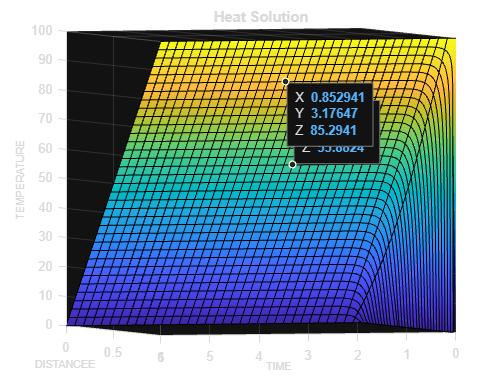


fsurf(v,[0 1 0 6])
title("Heat Solution")
xlabel('DISTANCEE','FontSize',8);
ylabel('TIME',"FontSize",8)
zlabel('TEMPERATURE','FontSize',8)

**Integral transform of ODE**

**example p.63**

**Take Fourier sisne from BC.**

clear
clc
clearvars
syms x t w u(x,t) U_s(w,t) Y(t) f(x) F_s(w)
Dt = diff(u,t);
D2x = diff(u,x,2);
eqn = fourier(Dt == D2x,x,w);
eqn = subs(eqn,{fourier(Dt,x,w),fourier(u,x,w)},{subs(Dt,{u,x},{U_s,w}),U_s-u(0,t)/w})

$$eqn(t) = \frac{\partial }{\partial t}U_{s}\left(w,t\right)=w^{2}\,\left(\frac{u\left(0,t\right)}{w}-U_{s}\left(w,t\right)\right)$$

eqn = subs(eqn,u(0,t),0)

$$eqn(t) = \frac{\partial }{\partial t}U_{s}\left(w,t\right)=-w^{2}\,U_{s}\left(w,t\right)$$

eqn = subs(eqn,U_s(w,t),Y(t))

$$eqn(t) = \frac{\partial }{\partial t}Y\left(t\right)=-w^{2}\,Y\left(t\right)$$

sol = dsolve(eqn);
sol = subs(sol,sym("C1"),F_s(w))

$$sol = {\mathrm{e}}^{-t\,w^{2}}\,F_{s}\left(w\right)$$

sol_x = simplify(int(sol*sin(w*x),w,[0 inf]))

$$sol\_x = \int_{0}^{\infty }{\mathrm{e}}^{-t\,w^{2}}\,F_{s}\left(w\right)\,\sin\left(w\,x\right)\mathrm{d}w$$

F_s(w) = simplify(int(f(x)*sin(w*x)*2/pi,x,[0 inf]))

$$F\_s(w) = \int_{0}^{\infty }\frac{2\,\sin\left(w\,x\right)\,f\left(x\right)}{\pi }\mathrm{d}x$$

u(x,t) = simplify(int((exp(-t*w^2)*sin(w*x))*F_s(w),w,[0 inf]))

$$u(x, t) = \int_{0}^{\infty }{\mathrm{e}}^{-t\,w^{2}}\,\sin\left(w\,x\right)\,\int_{0}^{\infty }\frac{2\,\sin\left(w\,x\right)\,f\left(x\right)}{\pi }\mathrm{d}x\mathrm{d}w$$

**Example p.18**

**Separation part**

clear 
clc 
syms x t u(x,t) L a f(x)
assume([L a],"positive")

**wave equation**

WaveEq = a^2*diff(u,x,2) == diff(u,t,2)

$$WaveEq(x, t) = a^{2}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0 ; BCL = u(L,t) ==0;
t0 = u(x,0) == f(x)

$$t0 = u\left(x,0\right)=f\left(x\right)$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == 0

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=0$$


syms T(t) X(x)
SepVar = subs(WaveEq,u(x,t),X(x)*T(t));

**conditions**

BC0 = subs(BC0,u(0,t),X(0))

$$BC0 = X\left(0\right)=0$$

BCL = subs(BCL,u(L,t),X(L))

$$BCL = X\left(L\right)=0$$

T0 = subs(t0,u(x,0),X(L))

$$T0 = X\left(L\right)=f\left(x\right)$$

DT = diff(T,t);
DT0 = subs(Dt0,Dt(x,0),DT(0))

$$DT0 = \left({\left(\frac{\partial }{\partial t}T\left(t\right)\right)|}_{t=0}\right)=0$$

SepVar = SepVar/(X(x)*T(t))

$$SepVar(x, t) = \frac{a^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}$$


syms lambda
assume(lambda,"positive")

**separation**

var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{a^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqT = var(2) == -lambda^2

$$eqT = \frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=-\lambda^{2}$$

X(x) = dsolve(eqX,BC0)

$$X(x) = -C_{1}\,\sin\left(\frac{\lambda \,x}{a}\right)$$

T(t) = dsolve(eqT,DT0)

$$T(t) = C_{1}\,\cos\left(\lambda \,t\right)$$

constantX = setdiff(symvar(X(x)),sym(['C',x,lambda,a]));
X(x) = subs(-X(x),constantX,sym('C2'))

$$X(x) = C_{2}\,\sin\left(\frac{\lambda \,x}{a}\right)$$

sln = X(L) == 0;

**filnding lambda**

[lambda, parameters,~] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer", "positive"]);
lambda = subs(lambda,parameters,n)

$$lambda = \frac{\pi \,a\,n}{L}$$

syms A_n ustruct(x,t);
sT(t) = subs(T(t),str2sym({'lambda','C1'}),{lambda,A_n});
sX(x) = subs(X(x),str2sym({'lambda','C2'}),{lambda,1});
ustruct(x,t,n) = sX(x)*sT(t)

$$ustruct(x, t, n) = A_{n}\,\cos\left(\frac{\pi \,a\,n\,t}{L}\right)\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

**Fourier series part**

syms Sigma
f0 = ustruct(x,0,n)

$$f0 = A_{n}\,\sin\left(\frac{\pi \,n\,x}{L}\right)$$

f0 = subs(f0,sym("A_n"),1);
f(x) = x;
An = subs(2/L*int(f*f0,x,[0 L]),L,1)

$$An = \frac{2\,\left(\sin\left(\pi \,n\right)-\pi \,n\,\cos\left(\pi \,n\right)\right)}{n^{2}\,\pi^{2}}$$

ustruct = subs(ustruct,{a,L,A_n},{1,1,2/L*int(f*f0,x,[0 L])})

$$ustruct(x, t, n) = \frac{2\,\sin\left(\pi \,n\,x\right)\,\cos\left(\pi \,n\,t\right)\,\left(L^{2}\,\sin\left(\pi \,n\right)-\pi \,L^{2}\,n\,\cos\left(\pi \,n\right)\right)}{L\,n^{2}\,\pi^{2}}$$

ustruct = subs(ustruct,{a,L},{1,1})

$$ustruct(x, t, n) = \frac{2\,\sin\left(\pi \,n\,x\right)\,\cos\left(\pi \,n\,t\right)\,\left(\sin\left(\pi \,n\right)-\pi \,n\,\cos\left(\pi \,n\right)\right)}{n^{2}\,\pi^{2}}$$

wavSol = symsum(ustruct(x,t,n),n,1,5)

$$wavSol = \frac{2\,\cos\left(\pi \,t\right)\,\sin\left(\pi \,x\right)}{\pi }-\frac{\cos\left(2\,\pi \,t\right)\,\sin\left(2\,\pi \,x\right)}{\pi }+\frac{2\,\cos\left(3\,\pi \,t\right)\,\sin\left(3\,\pi \,x\right)}{3\,\pi }-\frac{\cos\left(4\,\pi \,t\right)\,\sin\left(4\,\pi \,x\right)}{2\,\pi }+\frac{2\,\cos\left(5\,\pi \,t\right)\,\sin\left(5\,\pi \,x\right)}{5\,\pi }$$

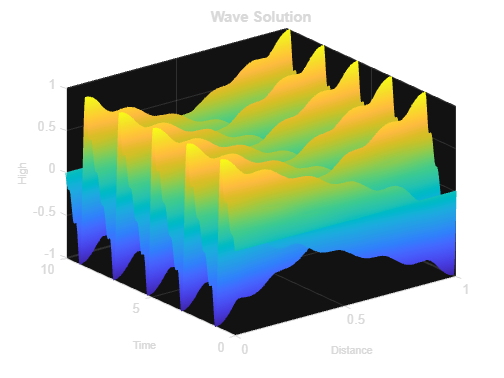

clf;figure
fsurf(wavSol,[0 1 0 10],"EdgeColor","interp")
title("Wave Solution")
xlabel('Distance','FontSize',8)
ylabel('Time','FontSize',8)
zlabel('High','FontSize',8)

clc
syms x t u(x,t) L a
assume([L a],"positive")
WaveEq = a^2*diff(u,x,2) == diff(u,t,2)

$$WaveEq(x, t) = a^{2}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\partial^{2}}{\partial t^{2}}u\left(x,t\right)$$

Dx = diff(u,x);
BC0 = u(0,t) == 0;BCL = Dx(L,t) == 0;
t0 = u(x,0) == x

$$t0 = u\left(x,0\right)=x$$

Dt = diff(u,t);
Dt0 = Dt(x,0) == 0

$$Dt0 = \left({\left(\frac{\partial }{\partial t}u\left(x,t\right)\right)|}_{t=0}\right)=0$$

syms T(t) X(x)
SepVar = subs(WaveEq,u(x,t),X(x)*T(t));
BC0 = subs(BC0,u(0,t),X(0))

$$BC0 = X\left(0\right)=0$$

BCL = subs(BCL,u(L,t),X(L))

$$BCL = \frac{\partial }{\partial L}X\left(L\right)=0$$

T0 = subs(t0,u(x,0),T(0))

$$T0 = T\left(0\right)=x$$

DT = diff(T,t);
DT0 = subs(Dt0,Dt(x,0),DT(0))

$$DT0 = \left({\left(\frac{\partial }{\partial t}T\left(t\right)\right)|}_{t=0}\right)=0$$

SepVar = SepVar/(X(x)*T(t))

$$SepVar(x, t) = \frac{a^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=\frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}$$

syms lambda
assume(lambda,"positive")
assumeAlso(lambda > 0)
var = children(SepVar);
eqX = var(1) == -lambda^2

$$eqX = \frac{a^{2}\,\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

eqT = var(2) == -lambda^2

$$eqT = \frac{\frac{\partial^{2}}{\partial t^{2}}T\left(t\right)}{T\left(t\right)}=-\lambda^{2}$$

X(x) = dsolve(eqX,BC0);
T(t) = dsolve(eqT,DT0)

$$T(t) = C_{1}\,\cos\left(\lambda \,t\right)$$

constantx = setdiff(symvar(X(x)),sym(['C',x,lambda,a]));
X(x) = subs(-X(x),constantx,sym('C2'))

$$X(x) = C_{2}\,\sin\left(\frac{\lambda \,x}{a}\right)$$

sln = subs(diff(X,x),x,L) == 0;
[lambda,parameters,cond] = solve(sln,lambda,"ReturnConditions",true);
n = sym("n",["integer","positive"]); L = 1;
lambda = subs(lambda,[parameters,sym("L")],[n L])

$$lambda = a\,\left(\frac{\pi }{2}+\pi \,n\right)$$

syms A utruct(x,t);
sT(t) = subs(T(t),str2sym({'lambda','C1'}),{lambda,A});
sX(x) = subs(X(x),str2sym({'lambda','C2'}),{lambda,1});
ustruct(x,t) = sX(x)*sT(t)

$$ustruct(x, t) = A\,\sin\left(x\,\left(\frac{\pi }{2}+\pi \,n\right)\right)\,\cos\left(a\,t\,\left(\frac{\pi }{2}+\pi \,n\right)\right)$$

Orthogonal Series Expansions

syms Sigma
bnum(n) = simplify(int(x*subs(ustruct(x,0),A,1),x,[0 L]));
bden(n) = simplify(int(subs(ustruct(x,0),A,1)^2,x,[0 L]));
A = bnum/bden

$$A(n) = \frac{8\,{\left(-1\right)}^{n}}{\pi^{2}\,{\left(2\,n+1\right)}^{2}}$$

waveStruct = subs(ustruct,sym("A"),A)

$$waveStruct(x, t) = \frac{8\,{\left(-1\right)}^{n}\,\sin\left(x\,\left(\frac{\pi }{2}+\pi \,n\right)\right)\,\cos\left(a\,t\,\left(\frac{\pi }{2}+\pi \,n\right)\right)}{\pi^{2}\,{\left(2\,n+1\right)}^{2}}$$

wavSol = [Sigma,waveStruct]

$$wavSol(x, t) = \left(\begin{array}{cc} \Sigma & \frac{8\,{\left(-1\right)}^{n}\,\sin\left(x\,\left(\frac{\pi }{2}+\pi \,n\right)\right)\,\cos\left(a\,t\,\left(\frac{\pi }{2}+\pi \,n\right)\right)}{\pi^{2}\,{\left(2\,n+1\right)}^{2}} \end{array}\right)$$